KINOVA Gen3 Manipulator

robot = loadrobot('kinovaGen3', 'DataFormat', 'row', "Gravity", [0 0 -9.81])

robot =   rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Shoulder_Link'  'HalfArm1_Link'  'HalfArm2_Link'  'ForeArm_Link'  'Wrist1_Link'  'Wrist2_Link'  'Bracelet_Link'  'EndEffector_Link'}
      BaseName: 'base_link'
       Gravity: [0 0 -9.8100]
    DataFormat: 'row'



currentRobotJConfig = homeConfiguration(robot)

currentRobotJConfig =      0     0     0     0     0     0     0



numJoints = numel(currentRobotJConfig)

numJoints = 7

endEffector = "EndEffector_Link"

endEffector = "EndEffector_Link"


timeStep = 0.1

timeStep = 0.1000

toolSpeed = 0.1

toolSpeed = 0.1000


jointInit = currentRobotJConfig

jointInit =      0     0     0     0     0     0     0


taskInit = getTransform(robot, jointInit, endEffector)

taskInit =     1.0000         0         0         0
         0    1.0000   -0.0000   -0.0249
         0    0.0000    1.0000    1.1854
         0         0         0    1.0000



taskFinal = trvec2tform([0.4 0 0.6])*axang2tform([0 1 0 pi])

taskFinal =    -1.0000         0    0.0000    0.4000
         0    1.0000         0         0
   -0.0000         0   -1.0000    0.6000
         0         0         0    1.0000


Generate Task-Space Trajectory

distance = norm(tform2trvec(taskInit) - tform2trvec(taskFinal))

distance = 0.7094


initTime = 0

initTime = 0

finalTime = (distance/toolSpeed) - initTime

finalTime = 7.0943

trajTimes = initTime: timeStep: finalTime

trajTimes =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


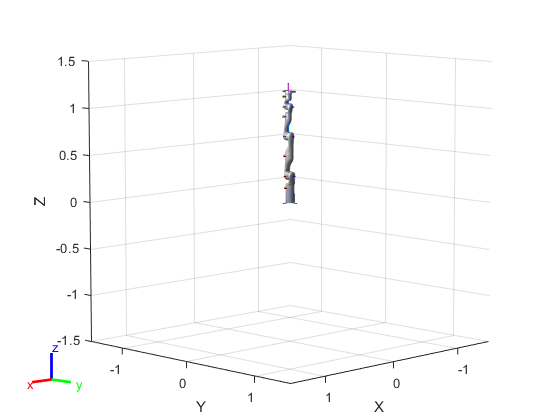

show(robot);